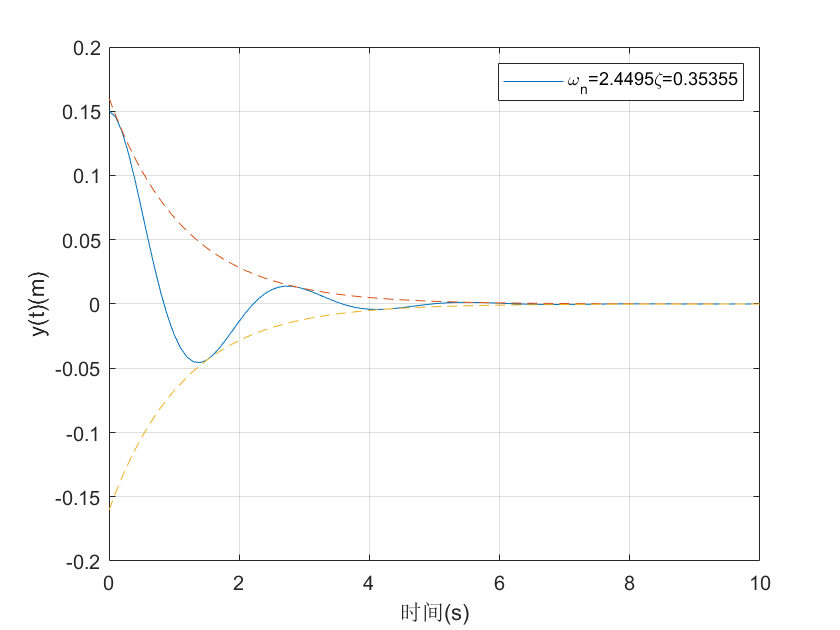


y0 = 0.15;
wn = sqrt(6);
zeta = 1/(2*sqrt(2));
t = [0:0.1:10];

%
c = (y0/sqrt(1-zeta^2));
y = c*exp(-zeta*wn*t).*sin(wn*sqrt(1-zeta^2)*t+acos(zeta));

bu = c*exp(-zeta*wn*t);
bl = -bu;

plot(t,y,t,bu,'--',t,bl,'--');
grid on
xlabel('时间(s)');
ylabel('y(t)(m)');
legend(['\omega_n=',num2str(wn),'\zeta=',num2str(zeta)]);